In this demo, we set the flow velocity to be 6, where the pipe system is under flutter. We construct a 2D unstable SSM around the unstable straight configuration. We expect there exists a stable limit cycle on the SSM. Under the addition of external control input at the free end, we are concerned with 

[1] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

%simple
%clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

clear all;
nmodes = 4;
fcload = 0;
flowspeed = 3;
miu = 0;
Gamma=0;
alpha=0.001;
beta=0.2;
[M, C, K, fnl, fExt, fphi, phimid] = buildModelsimple(nmodes,fcload,flowspeed,'first');%first在中点的挠度 

the first four eigenvalues for undamped system


lamd =   -0.0000 + 2.7832i
  -0.0000 - 2.7832i
  -0.0000 +35.2504i
  -0.0000 -35.2504i


n = size(M,1);

Create dynamical system 

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)
[V,D,W] = DS.linear_spectral_analysis();


 The first 8 nonzero eigenvalues are given as 
   1.0e+02 *

  -0.0004 + 0.0278i
  -0.0004 - 0.0278i
  -0.0078 + 0.3524i
  -0.0078 - 0.3524i
  -0.0394 + 0.8493i
  -0.0394 - 0.8493i
  -0.1248 + 1.5682i
  -0.1248 - 1.5682i



phiend = zeros(n,1);
lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
for k=1:n
   x    = 0.5;
   phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
        (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
   %phiend(k) = phin;
   phiend(k) = phimid(k);
   
end
% disp at the mid
obsfun = @(x,mapx,nmodes) mapx*x(1:nmodes,:);
obs = @(x) obsfun(x,phiend',n);

### Transient response prediction

tf     = 160; 
nsteps = 80000;
stepps=nsteps/tf;
z0     = 0.0*V(:,1); % initial condition (here we select it based on the modal shapes)
z0(1)  = 0.001;
outdof = 1:2*n;
set(DS,'u',[]);
[tInt,zInt] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z0);


### Stablization via LQR control


cont   = struct();
cont.Q    = zeros(2*n);
cont.Rhat = 0.1*(phiend'*phiend);
cont.Mhat = 1e4*eye(2*n)*(phiend'*phiend); % 1e4

Bext     = phiend;
% epsilon  = 1e-3;
epsilon  = 1;
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);

**Full dynamics simulation - without control**

om = 2*pi/tf;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

SSM Learn

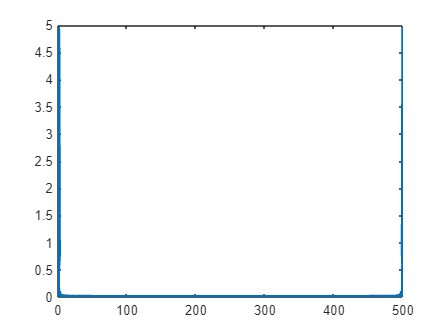

close all

%useddim=[2 5 8 11 14 17 20 24 27 30 33 36 39 42 ];
useddim=[1];
%useddim=[330 990 ]%1650 2310];
%useddim=linspace(1,44,44);
SSMstart=2000;

NMTEmin=10000000000000;

xalldimwo=zInt(:,1:n)*phiend;
Yfft=fft(xalldimwo);
plot(stepps/nsteps*(0:nsteps),abs(Yfft),"LineWidth",3)

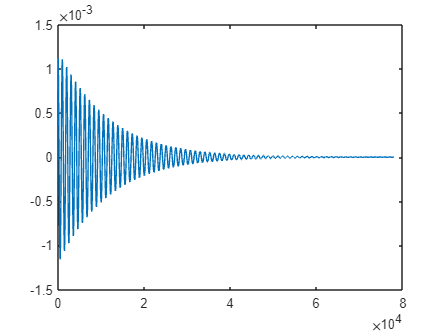

% for i=2:4
%      for j=3:8
%         for k=3:8
            SSMDim=2;
            xfullwoT=xalldimwo(SSMstart:end,useddim)';
            plot(xfullwoT(1,:))

            %xfullwoT=xfullwo(:,1)';
            lengthT=size(xfullwoT,2);
            tspan=linspace(0,lengthT/stepps,lengthT)

tspan =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980



            ydatac=cell(1,2);

            ydatac{1}=tspan;
            %ydatac{2}=xfullwoT(:,1:end-1);
            ydatac{2}=xfullwoT;
            
            overEmbed = 0;
            ydataembed = coordinatesEmbedding(ydatac, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.



            SSMOrder =5;
            % SSMOrder = 2;
            [IMInfo, SSMChart, SSMFunction] = IMGeometry(ydataembed, SSMDim, SSMOrder);%ydata可以是nxN的矩阵（zauto）

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.783096e-19    1.004e-03    8.406e-26

收敛于不可行点。

fmincon 已停止，因为当前步长小于
步长容差的值，但在约束容差值范围内不满足约束。

<停止条件详细信息>

请考虑启用内点法可行性模式。



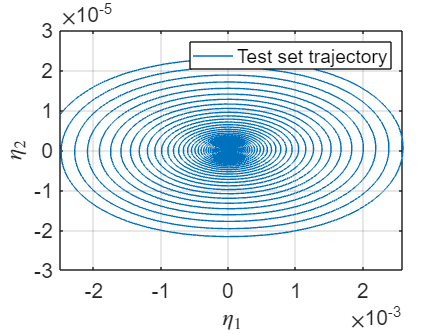


            yDataTrunc = sliceTrajectories(ydataembed, [10,159]);
            etaData = projectTrajectories(IMInfo, ydataembed);%Use the chart of a manifold to transform trajectories in the observable space to reduced coordinates on the manifold.
            etaDataTrunc = projectTrajectories(IMInfo, yDataTrunc);

            plotReducedCoordinates(etaData);%fig3 画出测试集和训练集的轨迹?
            legend({'Test set trajectory', 'Training set trajectory'})

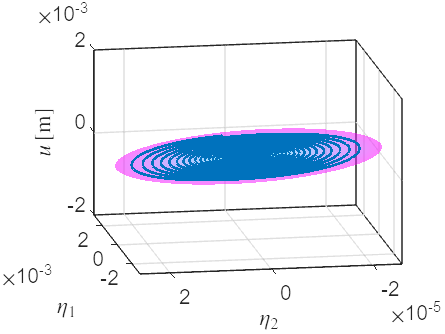



            plotSSMWithTrajectories(IMInfo, 1, ydataembed)%figure4 测试和流形
            view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1       0.00707681                        0.0176
     1           3       0.00413003             10         0.0126  
     2           4       0.00144783              1         0.0116  
     3           5      0.000773771              1        0.00316  
     4           6      0.000673555              1        0.00127  
     5           7       0.00064445              1       0.000728  
     6           8      0.000637278              1       0.000891  
     7           9      0.000631401              1       0.000383  
     8          10      0.000629122              1       0.000173  
     9          11      0.000628304              1       0.000136  
    10          12       0.00062706              1       0.000144  
    11          13

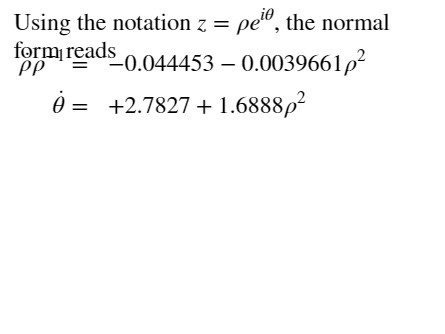


            % for k=3:10
                ROMOrder =4;
                RDInfo = IMDynamicsFlow(etaData,  'R_PolyOrd', ROMOrder, 'style', 'normalform');

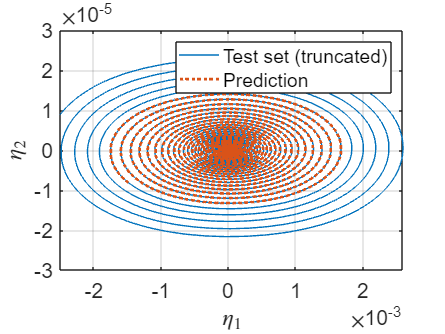

                %
                [yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunc);%通过流形 IMInfo 上 RDInfo 中的来advect yData 中的初始条件。？

                plotReducedCoordinates(etaData, etaRec)%测试和预测
                legend({'Test set (truncated)', 'Prediction'})

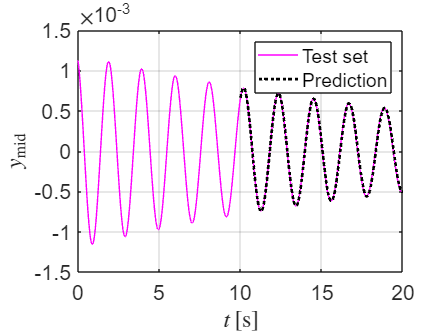

                %
                plotTrajectories(ydataembed, yRec, 'm', 'DisplayName', {'Test set', 'Prediction'})%fig7
                ylabel('$y_{\rm{mid}}$','Interpreter','latex')
                xlabel('$t \, [$s$]$','Interpreter','latex')


                normedTrajDist = computeTrajectoryErrors(yRec, ydataembed);
                NMTE = mean(normedTrajDist) % conjugacy error

NMTE = Inf

                if NMTE<NMTEmin
                    NMTEmin=NMTE;
                    iotm=i
                    jotm=j
                    kotm=k
                end


            % end
            %     end
            % end
            %xfullwoT=yRec{2};



% xfullwoTall=xalldimwo(200:end,4)';
% %xfullwoT=xfullwo(:,1)';
% lengthTall=size(xfullwoTall,2);
% tspan=linspace(0,lengthTall*0.00005,lengthTall)
% 
% ydataall=cell(1,2);
% 
% ydataall{1}=tspan;
% %ydatac{2}=xfullwoT(:,1:end-1);
% ydataall{2}=xfullwoTall;
% 
% ydatatestembed = coordinatesEmbedding(ydataall, SSMDim, 'OverEmbedding', overEmbed);
% 
% [yRectest, etaRectest, zRectest] = advect(IMInfo, RDInfo, ydatatestembed);
% 
% etaDatatest = projectTrajectories(IMInfo, ydatatestembed)
% plotReducedCoordinates(etaDatatest, etaRectest)%测试和预测
% legend({'Test set (truncated)', 'Prediction'})
% 
% plotTrajectories(ydatatestembed, yRectest, 'm', 'DisplayName', {'Test set', 'Prediction'})

TRAIN FOR DMD MULSP

close all

ustart=2000;
SSMstart=ustart;

multrainnum=30;
%urand=0.1*randi([-1,1],2,20000);
z0ssmstart=zInt(SSMstart+ustart,:);
omega0=1;


%urandspall=cell(1,trainnum);


urandtotalsp=[];
xalldimtotalsp=[]; 
xautototalsp=[];
%As=-1;

for A=1:2:16
    for k=1:multrainnum

        omegatrain=(omega0+(k-1)*2); %角频率w
        % omegatrain=(omega0^(k-1));
        utlength=ceil(2*pi/omegatrain*stepps);
        while utlength<20
            utlength=utlength+utlength;
        end
        urandallsp=zeros(1,utlength);
        
        %As=-1*As;

        for i=1:1:utlength
            for j=1:1

                urandallsp(j,i)=(0.0002*A)*1e0*sin(omegatrain/stepps*i);

            end
        end

        urandtotalsp=[urandtotalsp,urandallsp];

        %xautototalsp=[xautototalsp,yRec{2}(:,1:utlength)];

    end
end


totaldatalength=size(urandtotalsp,2)

totaldatalength = 67544

if totaldatalength>nsteps-ustart
    totaldatalength=nsteps-ustart;
    urandtotalsp=urandtotalsp(:,1:totaldatalength)
end
nstepsp=totaldatalength;
tfsp=(totaldatalength)/stepps;
urandtime=linspace(0,tfsp,nstepsp);
omsp = 2*pi/tfsp;
ufun = @(t) transpose(interp1(urandtime,urandtotalsp',t));
set(DS,'u',ufun)
[tfullwRcsp, xfullwRcsp,~,xalldimsp] = time_integration_transient(DS,omsp,'nCycles',...
    1, 'nSteps', nstepsp,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);


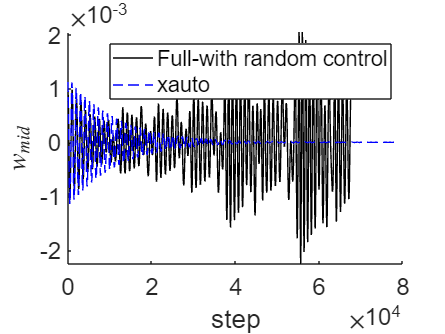



figure;hold on
plot(xalldimsp(:,1:4)*phiend,'k-','DisplayName', 'Full-with random control');
%plot(xalldimwo(1:9000,4)','r--','DisplayName', 'Full-without control')
plot(xalldimwo(SSMstart:end,1)','b--','DisplayName', 'xauto');
legend("show")
xlabel("step")
ylabel("$w_{mid}$",'Interpreter','latex')
set(gca,'FontSize',18)


figure()
timeurandtotalsp=linspace(0,size(urandtotalsp,2)/stepps,size(urandtotalsp,2))

timeurandtotalsp =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980


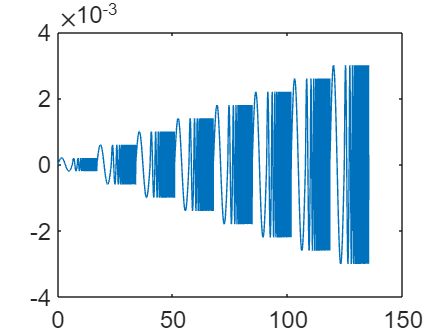

plot(timeurandtotalsp,urandtotalsp,'DisplayName', 'input u')
set(gca,'FontSize',18)

DMD

close all

%tcdim=100;
datalength=totaldatalength;
datastart=1;
%p=tcdim+2;
%r=1;
rembed=5;
windownum=1

windownum = 1

%auto1=yRec{2};
auto1=xfullwoT(:,ustart+1:end);
auto1=auto1(:,1:datalength);
xrc1=xalldimsp(:,1:4)*phiend;
xrc1=xrc1(1:datalength,:)';
X=(xrc1-auto1)/epsilon;

urand1=urandtotalsp%(1,SSMstart:SSMstart+datalength);

urand1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


nstepdmd=datalength;%总数据长度
tfdmd=(datalength)/stepps;
tspandmd=linspace(0,tfdmd,nstepdmd);


%%%%%%%%%%delay embed

DMDdim=3

DMDdim = 3

Xcell=cell(1,2);
ucell=cell(1,2);

Xcell{1}=tspandmd;
Xcell{2}=X(:,1:end);
ucell{1}=tspandmd;
ucell{2}=urand1;

overEmbed = 0;
Xembed = coordinatesEmbedding(Xcell, DMDdim, 'OverEmbedding', overEmbed);

The 7 embedding coordinates consist of the measured state and its 6 time-delayed measurements.


uembed = coordinatesEmbedding(ucell, 1, 'OverEmbedding', overEmbed);

The 3 embedding coordinates consist of the measured state and its 2 time-delayed measurements.


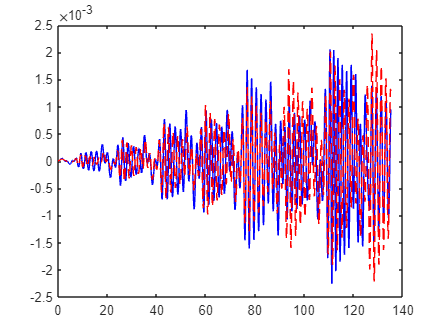

datalengthemb=size(Xembed{2},2)-1;
rembed=size(Xembed{2},1);

%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength-1,datastart,r,windownum,X,urand1);
%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,rembed,windownum,Xembed{2},uembed{2});
%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength,datastart,rembed,windownum,X,urand1);
[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,5,windownum,Xembed{2},urand1,0);

DMDtest

% utestlength=1000
% utest=zeros(1,utestlength);
% 
% for i=1:1:utestlength
%     utest(1,i)=(0.001)*1e0*sin(3/stepps*i);
% end
% nstepsp=utestlength;
% ttest=(utestlength)/stepps;
% utesttime=linspace(0,ttest,nstepsp);
% omsp = 2*pi/ttest;
% ufun = @(t) transpose(interp1(urandtime,utest',t));
% set(DS,'u',ufun)
% [ttest, xtestdmd,~,xalldimsp] = time_integration_transient(DS,omsp,'nCycles',...
%     1, 'nSteps', nstepsp,...
%     'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);
% auto2=xfullwoT(:,ustart:ustart+utestlength);
trainnum=1;
%urand=0.1*randi([-1,1],2,20000);

utlength=1000;
splength=utlength/trainnum;

nstepsp=utlength;%总数据长度
tfsp=(utlength)/stepps;
urandtime=linspace(0,tfsp,nstepsp)

urandtime =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0501    0.0521    0.0541    0.0561    0.0581    0.0601    0.0621    0.0641    0.0661    0.0681    0.0701    0.0721    0.0741    0.0761    0.0781    0.0801    0.0821    0.0841    0.0861    0.0881    0.0901    0.0921    0.0941    0.0961    0.0981


urandalltestsp=zeros(1,nstepsp);



for k=1:trainnum
    for i=1:1:splength
            urandalltestsp(1,i)=(0.001)*1e0*sin(13/stepps*i);
    end
     %urandallsp=[urandallsp,urandsp];
end

%set(DS,'D',Bext1)
omsp = 2*pi/tfsp;
ufun = @(t) transpose(interp1(urandtime,urandalltestsp',t));
%set(DS,'u',ufun);
set(DS,'u',ufun);


[tfulltestsp, xfulltestsp,~,xalldimtestsp] = time_integration_transient(DS,omsp,'nCycles',...
    1, 'nSteps', nstepsp,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

datalength=1000;%%%%%
tstest=linspace(0,datalength/stepps,datalength)

tstest =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0501    0.0521    0.0541    0.0561    0.0581    0.0601    0.0621    0.0641    0.0661    0.0681    0.0701    0.0721    0.0741    0.0761    0.0781    0.0801    0.0821    0.0841    0.0861    0.0881    0.0901    0.0921    0.0941    0.0961    0.0981



XRC=xalldimtestsp(1:datalength,1:4)*phiend;
u=urandalltestsp;
auto2=auto1(:,1:datalength)

auto2 = 1.0e-03 *

    0.9860    0.9844    0.9827    0.9810    0.9792    0.9774    0.9756    0.9737    0.9718    0.9698    0.9678    0.9658    0.9637    0.9616    0.9595    0.9573    0.9551    0.9528    0.9506    0.9482    0.9459    0.9435    0.9411    0.9386    0.9361    0.9336    0.9310    0.9284    0.9257    0.9230    0.9203    0.9176    0.9148    0.9120    0.9091    0.9062    0.9033    0.9003    0.8974    0.8943    0.8913    0.8882    0.8851    0.8819    0.8788    0.8755    0.8723    0.8690    0.8657    0.8623


Xtest=XRC'-auto2

Xtest = 1.0e-04 *

         0   -0.0001   -0.0002   -0.0003   -0.0004   -0.0003   -0.0003   -0.0002   -0.0000    0.0001    0.0003    0.0006    0.0008    0.0012    0.0015    0.0018    0.0022    0.0026    0.0031    0.0035    0.0040    0.0046    0.0052    0.0058    0.0064    0.0072    0.0079    0.0087    0.0096    0.0105    0.0114    0.0124    0.0134    0.0144    0.0155    0.0166    0.0177    0.0189    0.0201    0.0214    0.0228    0.0242    0.0257    0.0272    0.0289    0.0306    0.0324    0.0343    0.0363    0.0384


% u=urand;
% XRC=xfulltestwRc';
Xtestcell=cell(1,2);
utestcell=cell(1,2);


Xtestcell{1}=tstest(1:end-1);
Xtestcell{2}=Xtest(:,1:size(Xtestcell{1},2));
utestcell{1}=tstest(1:end-1);
utestcell{2}= urandalltestsp(:,1:size(Xtestcell{1},2));

overEmbed = 0;
Xtestembed = coordinatesEmbedding(Xtestcell, DMDdim, 'OverEmbedding', overEmbed);

The 7 embedding coordinates consist of the measured state and its 6 time-delayed measurements.


utestembed = coordinatesEmbedding(utestcell, DMDdim, 'OverEmbedding', overEmbed);

The 7 embedding coordinates consist of the measured state and its 6 time-delayed measurements.


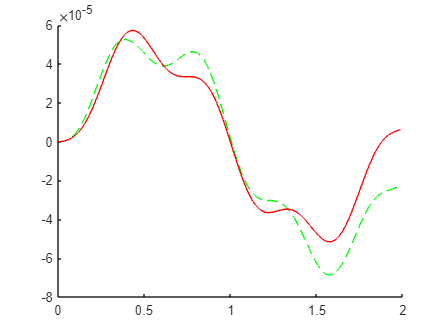

datalengthemb=size(Xtestembed{2},2)-1;

N=datalength;

xt2=zeros(size(Admv{1},2),N);
ut=zeros(size(Bdmv{1},2),N);
xt2(:,1)=Xtestembed{2}(:,1)/epsilon;
%u=urandall{testnum};

%X2=XRC-auto1;

for k =1:datalength-1
        ut(:,k)=u(:,k);

        xt2(:,k+1)=epsilon*(Admv{1}*xt2(:,k)+Bdmv{1}*ut(:,k));

end

figlength=size(Xtestembed{2},2);
figx=linspace(0,figlength/500,figlength);
figure()
hold on
%plot(figx,xt(1,1:figlength),'b','DisplayName', 'test DMD 5d')
plot(figx,Xtestembed{2}(1,:),'g--','DisplayName', 'test origin')
plot(figx,xt2(1,1:figlength),'r','DisplayName', 'test DMD 7d')

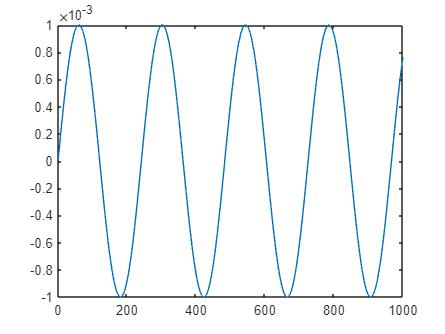


figure()
plot( urandalltestsp)

LQR

close all

LQRlength=3000;

tspan1=linspace(datastart,datastart+LQRlength,LQRlength);
autodata=xalldimwo(SSMstart+1:SSMstart+LQRlength,useddim)';
epsil=DS.epsilon;


%z00=autodata(:,1);
autocell=cell(1,2);

tspanLQR=linspace(0,LQRlength/stepps,LQRlength)
autocell{1}=tspanLQR(:,1:LQRlength);
autocell{2}=autodata(:,1:LQRlength);

autoembed = coordinatesEmbedding(autocell, DMDdim, 'OverEmbedding', overEmbed);

% Ecell=cell(1,2)
% Ecell{1}=tspanLQR(:,1:LQRlength);
% xalldimwET=xalldimwE';
% Ecell{2}=xalldimwET(useddim,SSMstart+1:SSMstart+LQRlength);
% Eembed = coordinatesEmbedding(Ecell, DMDdim, 'OverEmbedding', overEmbed);

targetdata=autoembed{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed{2},2);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj = LQRwdz3(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed{2},targetdata,windownum,epsil,DS,1,0.6)


figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
plot(prenewtraj.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(autoembed{2}(2,:),'--r','DisplayName', 'Full-without control')
%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj.us,2)/stepps,size(prenewtraj.us,2))
plot(figx,prenewtraj.us(1,:),'r','DisplayName', 'lqr us')
%xlim([0,0.1])

realsystem1

utnew=[prenewtraj.us(1,:)];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew,2)/stepps,size(utnew,2))
%closedtime=0:h:0.65-h;
prestep=size(utnew,2)
tpref=size(utnew,2)/stepps;

%z0ssmstart=xalldimwE(SSMstart+1,:)

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figlength=size(xfullpre,1)-1;

xreal=xfullpre(1:figlength,1:4)*phiend;

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xfullpre,1)-100;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xreal(1:figlength),'g','DisplayName', 'real Full-with control');
plot(figx, autoembed{2}(2,1:figlength),'r--','DisplayName', 'Full-without control');
plot(figx, prenewtraj.xt(2,1:figlength),'--b','DisplayName', 'pre Full-with control')

% plot( xf(1:figlength),'g','DisplayName', 'real Full-with control');
% plot( autoembed{2}(2,1:figlength),'r--','DisplayName', 'Full-without control');
% plot(prexf(1:figlength),'--b','DisplayName', 'pre Full-with control')

%xlim([0,0.02])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')
%set(gca,'FontSize',18)


DMD2

% urandtotalsp2=[utnew,urandtotalsp];
% 
% totaldatalength2=size(urandtotalsp2,2)
% 
% if totaldatalength2>nsteps-ustart
%     totaldatalength2=nsteps-ustart;
%     urandtotalsp2=urandtotalsp2(:,1:totaldatalength2)
% end
% nstepsp=totaldatalength2;
% tfsp=(totaldatalength2)/stepps;
% urandtime=linspace(0,tfsp,nstepsp);
% omsp = 2*pi/tfsp;
% ufun = @(t) transpose(interp1(urandtime,urandtotalsp2',t));
% set(DS,'u',ufun)
% [tfullwRcsp2, xfullwRcsp2,~,xalldimsp2] = time_integration_transient(DS,omsp,'nCycles',...
%     1, 'nSteps', nstepsp,...
%     'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);
% 
% 
% %tcdim=100;
% datalength2=totaldatalength2;
% datastart=1;
% %p=tcdim+2;
% %r=1;
% rembed=5;
% windownum=1
% %auto1=yRec{2};
% auto1=xfullwoT(:,ustart:end);
% auto1=auto1(:,1:datalength2);
% xrc1=xfullwRcsp2(:,1:4)*phiend;
% xrc1=xrc1(1:datalength2,:)';
% X=(xrc1-auto1)/epsilon;
% 
% urand1=urandtotalsp2%(1,SSMstart:SSMstart+datalength);
% nstepdmd=datalength2;%总数据长度
% tfdmd=(datalength2)/stepps;
% tspandmd=linspace(0,tfdmd,nstepdmd);
% 
% 
% %%%%%%%%%%delay embed
% 
% %DMDdim=3
% 
% Xcell=cell(1,2);
% ucell=cell(1,2);
% 
% Xcell{1}=tspandmd;
% Xcell{2}=X(:,1:end);
% ucell{1}=tspandmd;
% ucell{2}=urand1;
% 
% overEmbed = 0;
% Xembed = coordinatesEmbedding(Xcell, DMDdim, 'OverEmbedding', overEmbed);
% uembed = coordinatesEmbedding(ucell, 1, 'OverEmbedding', overEmbed);
% datalengthemb=size(Xembed{2},2)-1;
% rembed=size(Xembed{2},1);
% 
% %[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength-1,datastart,r,windownum,X,urand1);
% %[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,rembed,windownum,Xembed{2},uembed{2});
% %[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalength,datastart,rembed,windownum,X,urand1);
% [Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,30,windownum,Xembed{2},urand1,0);

feedback test 1

feedbackpoint1=800;
utnewhalf=[prenewtraj.us(1,1:feedbackpoint1),zeros(1,LQRlength-feedbackpoint1)];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnewhalf,2)/stepps,size(utnewhalf,2))
%closedtime=0:h:0.65-h;
prestep=size(utnewhalf,2)
tpref=size(utnewhalf,2)/stepps;

%z0ssmstart=xalldimwE(SSMstart+1,:)

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnewhalf',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre,alldimfbpoint1,xalldimreal] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);



figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=2900;
figx=linspace(0,figlength/stepps,figlength);



plot(figx, xreal(1:figlength),'g','DisplayName', 'real Full-with control');
plot(figx, autoembed{2}(2,1:figlength),'r--','DisplayName', 'Full-without control');
plot(figx, prenewtraj.xt(2,1:figlength),'--b','DisplayName', 'pre Full-with control')
legend("show")
xlabel("t[s]")
ylabel("$y_{mid}$",'Interpreter','latex')
%set(gca,'FontSize',18)

xbehindtemp=xalldimreal(1:figlength,1:4)*phiend;
xbehind=xbehindtemp(feedbackpoint1:end,useddim)';
%xbh1=xbehind(:,1);
% xbhtest=[];
% for i=1:5000
%     xbhtest=[xbhtest,xbh1];
% end

xbehindcell=cell(1,2)
xbehindcell{1}=tspanLQR(:,1:size(xbehind,2));
%xbehindcell{2}=xbehind;
xbehindcell{2}=xbehind;
xbehindembed = coordinatesEmbedding(xbehindcell, SSMDim, 'OverEmbedding', overEmbed);
 [xbhRec, etabhRec, zbhRec] = advect(IMInfo, RDInfo, xbehindembed);
 figure();
 hold on;
 plot(xbhRec{2}(2,:),'r','DisplayName', 'predict');
 plot(xbehind(1,:),'b','DisplayName', 'origin')
 legend("show")
xlabel("steps")
ylabel("$d_{mid}$",'Interpreter','latex')




LQRlength2=size(xbhRec{2},2);

tspan2=linspace(datastart,datastart+LQRlength2-1,LQRlength2);
%autodata2=xbehind;
autodata2=xbhRec{2}(1,:);

autocell2=cell(1,2);

tspanLQR2=linspace(0,LQRlength2/stepps,LQRlength2)
autocell2{1}=tspanLQR2(:,1:LQRlength2);
autocell2{2}=autodata2(:,1:LQRlength2);

autoembed2 = coordinatesEmbedding(autocell2, DMDdim, 'OverEmbedding', overEmbed);

xbhcell=cell(1,2)
xbhcell{1}=tspanLQR2(:,1:LQRlength2);
xbhcell{2}=xbehind(:,1:LQRlength2);
xbhembeded = coordinatesEmbedding(xbhcell, DMDdim, 'OverEmbedding', overEmbed);

%targetdata2=autoembed2{2};
targetdata2=xbhembeded{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed2{2},2);

%[Admv,Bdmv,Uupmv,datastartmv,datalengthmv]=DMD1(datalengthemb,datastart,5,windownum,Xembed{2},urand1,0);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj2 = LQRwdz3(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed2{2},targetdata2,windownum,epsil,DS,1,6)


figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
figx=linspace(0,size(prenewtraj2.xt,2)/stepps,size(prenewtraj2.xt,2));
plot(figx,prenewtraj2.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(figx,autoembed2{2}(2,:),'r','DisplayName', 'Full-without control')
%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj2.us,2)/stepps,size(prenewtraj2.us,2))
plot(figx,prenewtraj2.us(1,:),'r','DisplayName', 'lqr us')

feedback real system1

utnew2=[prenewtraj.us(:,1:feedbackpoint1),prenewtraj2.us];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew2,2)/stepps,size(utnew2,2))
%closedtime=0:h:0.65-h;
prestep=size(utnew2,2);
tpref=size(utnew2,2)/stepps;

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew2',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);


figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xfullpre,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xfullpre(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx, autoembed{2}(2,1:figlength),'r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
plot(figx, [prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:figlength-feedbackpoint1)],'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("t[s]")
ylabel("$y_{mid}$",'Interpreter','latex')


figure()
plot(figx,utnew2(1:figlength),'DisplayName', 'pre Full-with control')

feedback test 2

feedbackpoint2=1400;
utnewhalf2=[utnew2(1,1:feedbackpoint2),zeros(1,LQRlength-feedbackpoint2)];
%utnew=[zeros(1,3000),100*ones(1,10000)]

tpref2=size(utnewhalf2,2)/stepps;
closedtime2=linspace(0,tpref2,size(utnewhalf2,2))
%closedtime=0:h:0.65-h;
prestep2=size(utnewhalf2,2)

om = 2*pi/tpref2;
ufun = @(t) transpose(interp1(closedtime2,utnewhalf2',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre2, xfullpre2,~,xalldimreal2] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep2,...
    'integrationMethod','ode15s','outdof',outdof,'init',z0ssmstart);

figure;
hold on
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xalldimreal2,1)-2;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimreal2(1:figlength,1:4)*phiend,'g','DisplayName', 'real Full-with feedback-control');
plot(figx,  xalldimwo(SSMstart+1:SSMstart+figlength,1)','r--','DisplayName', 'Full-without control');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
%plot(figx, [prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:figlength-feedbackpoint1)],'--b','DisplayName', 'pre Full-with control')
%xlim([0,0.2])
legend("show")
xlabel("t(s)")
ylabel("$d_{mid}$",'Interpreter','latex')


xbehind2=xalldimreal2(feedbackpoint2+1:end-1,1:4)*phiend;
xbehind2=xbehind2'
%xbh1=xbehind(:,1);
% xbhtest=[];
% for i=1:5000
%     xbhtest=[xbhtest,xbh1];
% end

xbehindcell2=cell(1,2)
xbehindcell2{1}=tspanLQR(:,1:size(xbehind2,2));
xbehindcell2{2}=xbehind2;
xbehindembed2 = coordinatesEmbedding(xbehindcell2, SSMDim, 'OverEmbedding', overEmbed);

 [xbhRec2, etabhRec, zbhRec] = advect(IMInfo, RDInfo, xbehindembed2);
 figure();
 hold on;
 plot(xbhRec2{2}(1,:),'r','DisplayName', 'predict');
 plot(xbehind2(1,:),'b','DisplayName', 'origin')
 legend("show")
xlabel("steps")
ylabel("$d_{mid}$",'Interpreter','latex')




LQRlength3=LQRlength-feedbackpoint2-2*DMDdim;

tspan3=linspace(datastart,datastart+LQRlength3-1,LQRlength3);
%autodata2=xbehind;
autodata3=xbhRec2{2}(1,:);

autocell3=cell(1,2);

tspanLQR3=linspace(0,LQRlength3/stepps,LQRlength3)
autocell3{1}=tspanLQR3(:,1:LQRlength3);
autocell3{2}=autodata3(:,1:LQRlength3);
autoembed3 = coordinatesEmbedding(autocell3, DMDdim, 'OverEmbedding', overEmbed);

xbhcell2=cell(1,2)
xbhcell2{1}=tspanLQR2(:,1:LQRlength3);
xbhcell2{2}=xbehind2(:,1:LQRlength3);
xbhembeded2 = coordinatesEmbedding(xbhcell2, DMDdim, 'OverEmbedding', overEmbed);


%targetdata2=autoembed2{2};
targetdata3=xbhembeded2{2};


datastartmv=cell(1,windownum);
datalengthLQRmv=cell(1,windownum);
datastartmv{1}=datastart;
datalengthmvLQR{1}=size(autoembed3{2},2);

%prenewtraj = LQRwdz(tspan1,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmv,autodata,targetdata,windownum,epsil,DS)
prenewtraj3 = LQRwdz3(tspan3,cont,Uupmv,Admv,Bdmv,datastartmv,datalengthmvLQR,autoembed3{2},targetdata3,windownum,epsil,DS,1,10)


figure()
hold on
%plot(pretraj0auto.us(1,:),'r')
%plot(pretraj0auto.mlus(1,:),'b')
figx=linspace(0,size(prenewtraj3.xt,2)/stepps,size(prenewtraj3.xt,2));
plot(figx,prenewtraj3.xt(2,:),'-b','DisplayName', 'Full-with control')
plot(figx,autoembed3{2}(2,:),'r','DisplayName', 'Full-without control')
%plot(xalldimwo(SSMstart:SSMstart+utlength,11)','r','DisplayName', 'Full-without control')
%xlim([0 12000])
%ylim([-0.1 0.1])
figure()
figx=linspace(0,size(prenewtraj3.us,2)/stepps,size(prenewtraj3.us,2))
plot(figx,prenewtraj3.us(1,:),'r','DisplayName', 'lqr us')

feedback real system2

utnew3=[utnew2(1,1:feedbackpoint2),0.04*prenewtraj3.us];
%utnew=[zeros(1,3000),100*ones(1,10000)]


closedtime=linspace(0,size(utnew3,2)/stepps,size(utnew3,2))
%closedtime=0:h:0.65-h;
prestep=size(utnew3,2);
tpref=size(utnew3,2)/stepps;

om = 2*pi/tpref;
ufun = @(t) transpose(interp1(closedtime,utnew3',t,'linear','extrap'));
set(DS,'u',ufun);
[tfullpre, xfullpre,~,xalldimpre3] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', prestep,...
    'integrationMethod','ode45','outdof',outdof,'init',z0ssmstart);


figure;
hold on
feedbacktraj2=[prenewtraj.xt(1,1:feedbackpoint1),prenewtraj2.xt(1,1:feedbackpoint2-feedbackpoint1),prenewtraj3.xt(1,1:end)];
%plot(traj_closed.time, traj_closed.zt(1,:),'m--','DisplayName','SSM-closed-control');
figlength=size(xalldimpre3,1)-24;
figx=linspace(0,figlength/stepps,figlength);
plot(figx, xalldimpre3(1:figlength,1:4)*phiend,'g','DisplayName', 'real-with control traj');
plot(figx,  xalldimwo(SSMstart+24:SSMstart+23+figlength,1)','r-.','DisplayName', 'without control traj');
%plot(figx, xalldimreal(1:figlength,1:4)*phiend,'k','DisplayName', 'real Full-with control');
plot(figx, feedbacktraj2(23:22+size(figx,2)),'--b','DisplayName', 'pre-with control')
%xlim([0,0.2])
legend("show")
xlabel("t[\rm{s}]",'Interpreter','latex')
ylabel("$d_{\rm{mid}}$",'Interpreter','latex')
figure()
plot(figx, utnew3(:,23:end-1),'b','DisplayName', 'ut');

